# HW 9 Runtime Data Graph

Andrew Brown: 11/25/2020

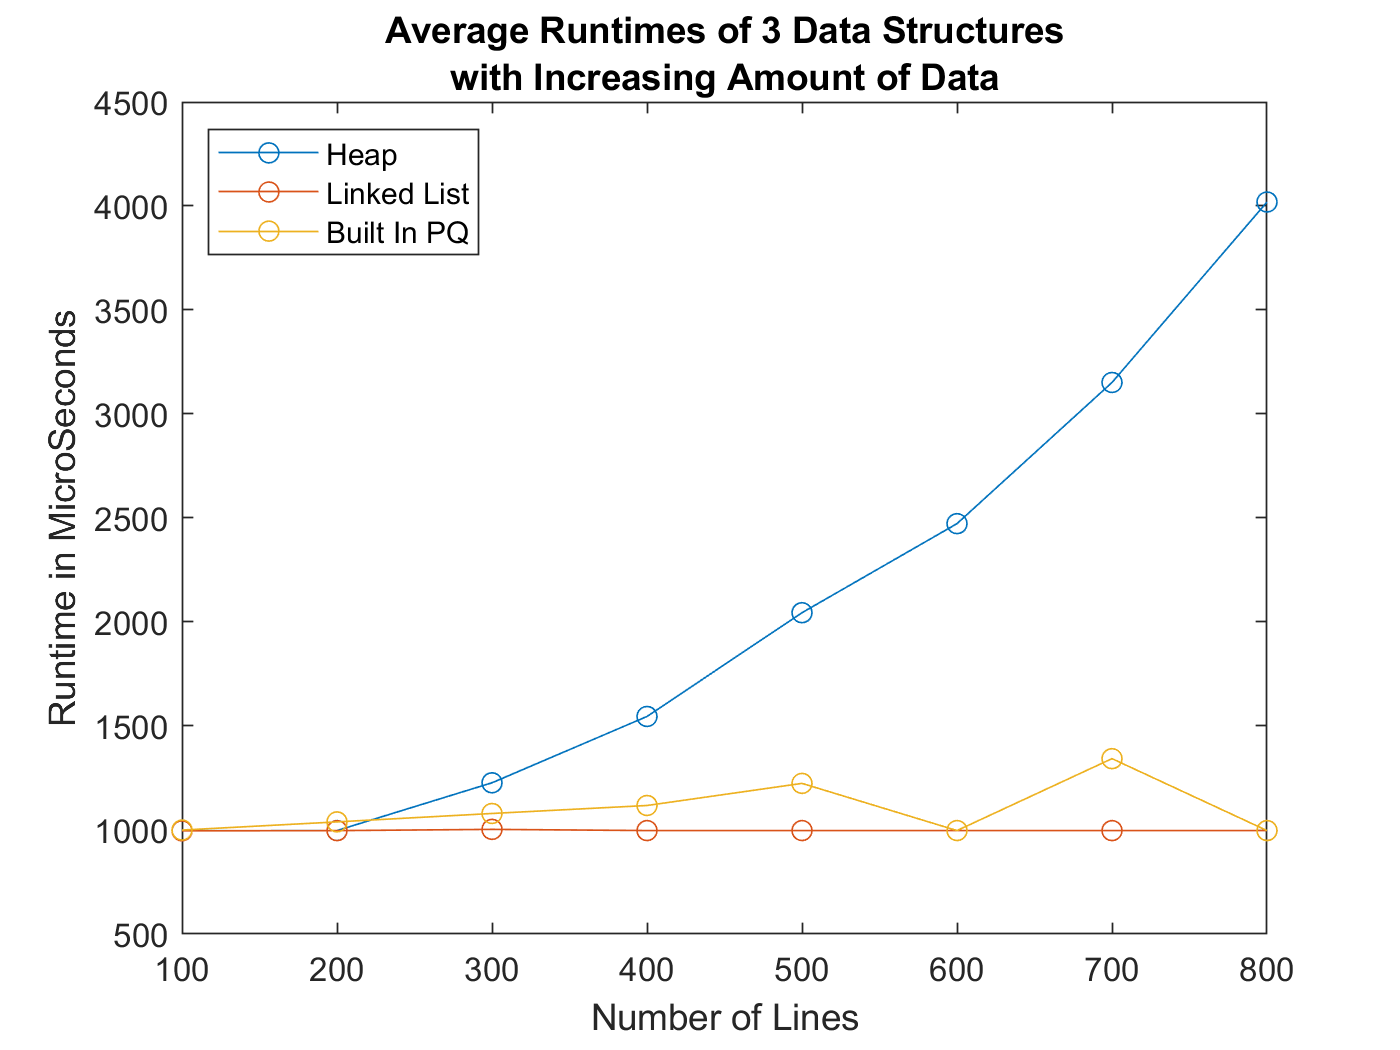

%C Clear Stuff
clc
clear all
close all

% Import data
rawHeapData = readmatrix('heapData.txt');
rawLLData = readmatrix('linkedListData.txt');
rawBuiltInData = readmatrix('builtInData.txt');

% Store array of number of lines.
nums = 100:100:800;

% Copy raw data.
heapData = rawHeapData;
llData = rawLLData;
biData = rawBuiltInData;

% Make all 0 values NaNs for later omitance.
for i=1:8
    for j=1:100
        if rawHeapData(j,i) == 0
            heapData(j,i) = nan;
        end
    end
end
for i=1:8
    for j=1:100
        if rawLLData(j,i) == 0
            llData(j,i) = nan;
        end
    end
end
for i=1:8
    for j=1:100
        if rawBuiltInData(j,i) == 0
            biData(j,i) = nan;
        end
    end
end

% Store heap means in array
heapMeans = [mean(heapData(:,1),'omitnan'), mean(heapData(:,2),'omitnan'),mean(heapData(:,3),'omitnan'),...
    mean(heapData(:,4),'omitnan'),mean(heapData(:,5),'omitnan'),mean(heapData(:,6),'omitnan'),...
    mean(heapData(:,7),'omitnan'),mean(heapData(:,8),'omitnan'),];

% Store Linked List means in array
llMeans = [mean(llData(:,1),'omitnan'), mean(llData(:,2),'omitnan'),mean(llData(:,3),'omitnan'),...
    mean(llData(:,4),'omitnan'),mean(llData(:,5),'omitnan'),mean(llData(:,6),'omitnan'),...
    mean(llData(:,7),'omitnan'),mean(llData(:,8),'omitnan'),];

% Store Builtin PQ means in array
biMeans = [mean(biData(:,1),'omitnan'), mean(biData(:,2),'omitnan'),mean(biData(:,3),'omitnan'),...
    mean(biData(:,4),'omitnan'),mean(biData(:,5),'omitnan'),mean(biData(:,6),'omitnan'),...
    mean(biData(:,7),'omitnan'),mean(biData(:,8),'omitnan'),];

% Store Heap SDs in array
heapSD = [std(heapData(:,1),'omitnan'), std(heapData(:,2),'omitnan'),std(heapData(:,3),'omitnan'),...
    std(heapData(:,4),'omitnan'),std(heapData(:,5),'omitnan'),std(heapData(:,6),'omitnan'),...
    std(heapData(:,7),'omitnan'),std(heapData(:,8),'omitnan'),];

% Store Linked List SDs in array
llSD = [std(llData(:,1),'omitnan'), std(llData(:,2),'omitnan'),std(llData(:,3),'omitnan'),...
    std(llData(:,4),'omitnan'),std(llData(:,5),'omitnan'),std(llData(:,6),'omitnan'),...
    std(llData(:,7),'omitnan'),std(llData(:,8),'omitnan'),];

% Store Builtin PQ SDs in array
biSD = [std(biData(:,1),'omitnan'), std(biData(:,2),'omitnan'),std(biData(:,3),'omitnan'),...
    std(biData(:,4),'omitnan'),std(biData(:,5),'omitnan'),std(biData(:,6),'omitnan'),...
    std(biData(:,7),'omitnan'),std(biData(:,8),'omitnan'),];


figure;
plot(nums,heapMeans,'-o');
hold on
plot(nums,llMeans,'-o');
plot(nums,biMeans,'-o');
xlabel("Number of Lines");
ylabel("Runtime in MicroSeconds")
legend('Heap','Linked List','Built In PQ',"Location",'northwest');
title("Average Runtimes of 3 Data Structures"+newline+"with Increasing Amount of Data");
hold off

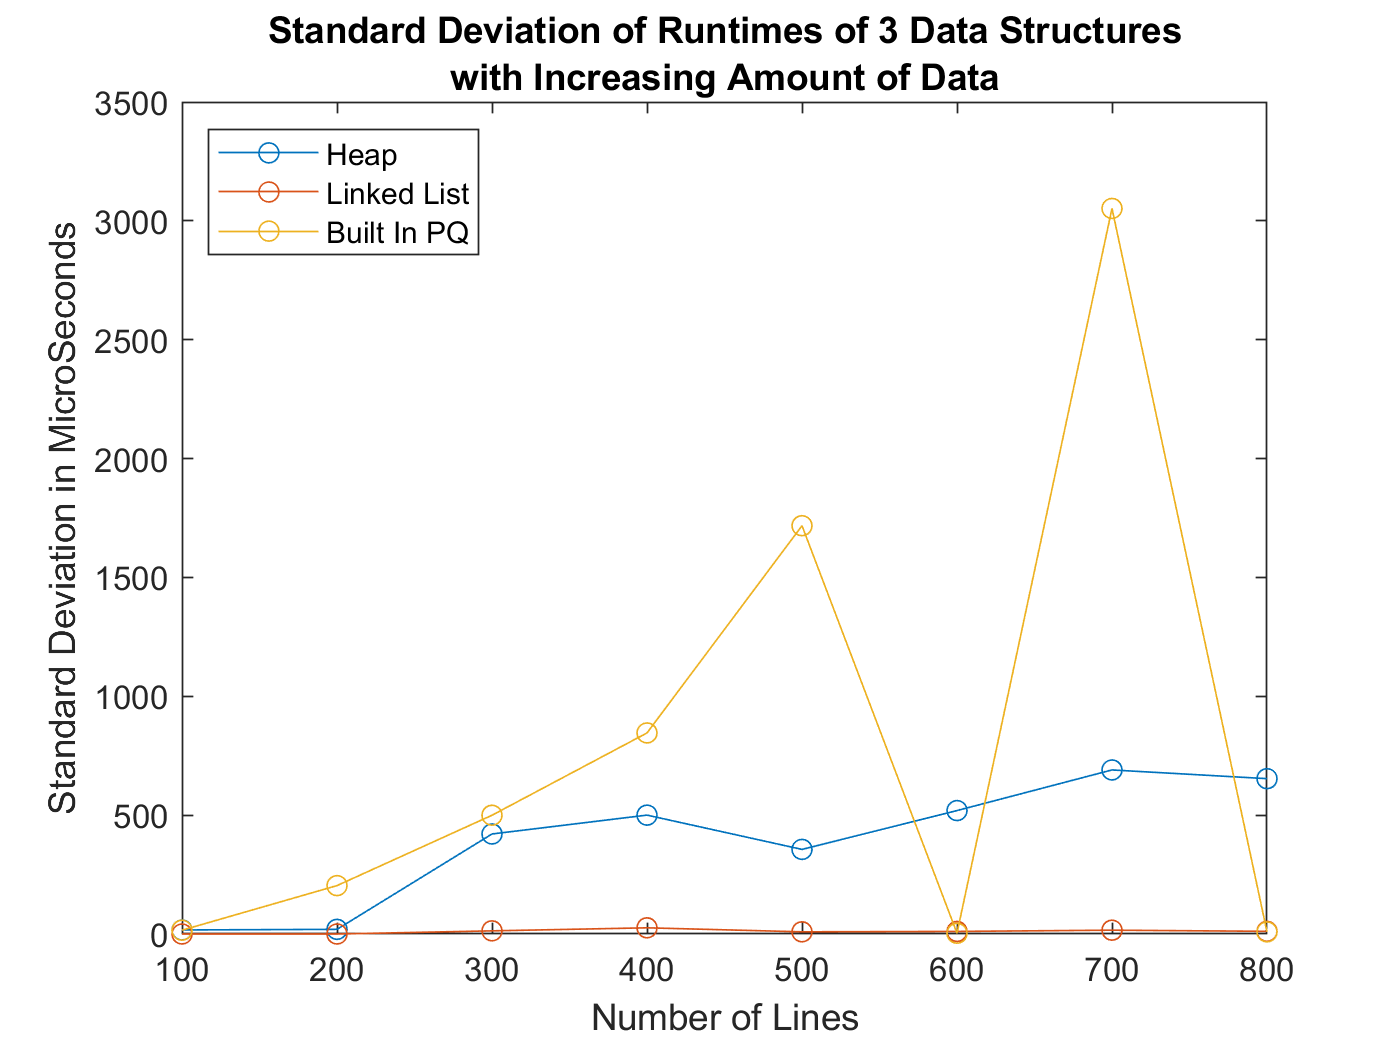

figure;
plot(nums,heapSD,'-o');
hold on
plot(nums,llSD,'-o');
plot(nums,biSD,'-o');
xlabel("Number of Lines");
ylabel("Standard Deviation in MicroSeconds")
legend('Heap','Linked List','Built In PQ',"Location",'northwest');
title("Standard Deviation of Runtimes of 3 Data Structures"+newline+"with Increasing Amount of Data");